load test_data
run_Callback(hObject, eventdata, handles)
h = get(gca,'Children')
x = get(h(2),'xdata')
y = get(h(2),'ydata')
test_data = [x' ; y']

yy=y

yy =   112.8249  112.8249  112.8249  112.8249  112.8249  112.8248  112.8248  112.8247  112.8246  112.8245  112.8242  112.8239  112.8234  112.8229  112.8221  112.8212  112.8201  112.8188  112.8172  112.8153  112.8132  112.8107  112.8078  112.8046  112.8010  112.7970  112.7925  112.7876  112.7821  112.7762  112.7697  112.7627  112.7551  112.7469  112.7381  112.7287  112.7187  112.7080  112.6966  112.6845  112.6718  112.6583  112.6441  112.6292  112.6135  112.5970  112.5798  112.5618  112.5430  112.5234


for i=1:numel(yy)/5
    yy(i) = yy(i*5);
end
yy = yy(1:numel(yy)/7)

yy =   112.8249  112.8245  112.8221  112.8153  112.8010  112.7762  112.7381  112.6845  112.6135  112.5234  112.4134  112.2826  112.1307  111.9577  111.7636  111.5488  111.3138  111.0594  110.7863  110.4953  110.1874  109.8634  109.5245  109.1716  108.8056  108.4275  108.0384  107.6391  107.2305  106.8136  106.3890  105.9578  105.5205  105.0779  104.6306  104.1794  103.7249  103.2675  102.8078  102.3464  101.8836  101.4199  100.9558  100.4915  100.0276   99.5642   99.1017   98.6404   98.1805   97.7223



d = yy

d =   112.8249  112.8245  112.8221  112.8153  112.8010  112.7762  112.7381  112.6845  112.6135  112.5234  112.4134  112.2826  112.1307  111.9577  111.7636  111.5488  111.3138  111.0594  110.7863  110.4953  110.1874  109.8634  109.5245  109.1716  108.8056  108.4275  108.0384  107.6391  107.2305  106.8136  106.3890  105.9578  105.5205  105.0779  104.6306  104.1794  103.7249  103.2675  102.8078  102.3464  101.8836  101.4199  100.9558  100.4915  100.0276   99.5642   99.1017   98.6404   98.1805   97.7223


numTimeStepsTrain = floor(0.9*numel(d));

dataTrain = d(1:numTimeStepsTrain+1);
dataTest = d(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

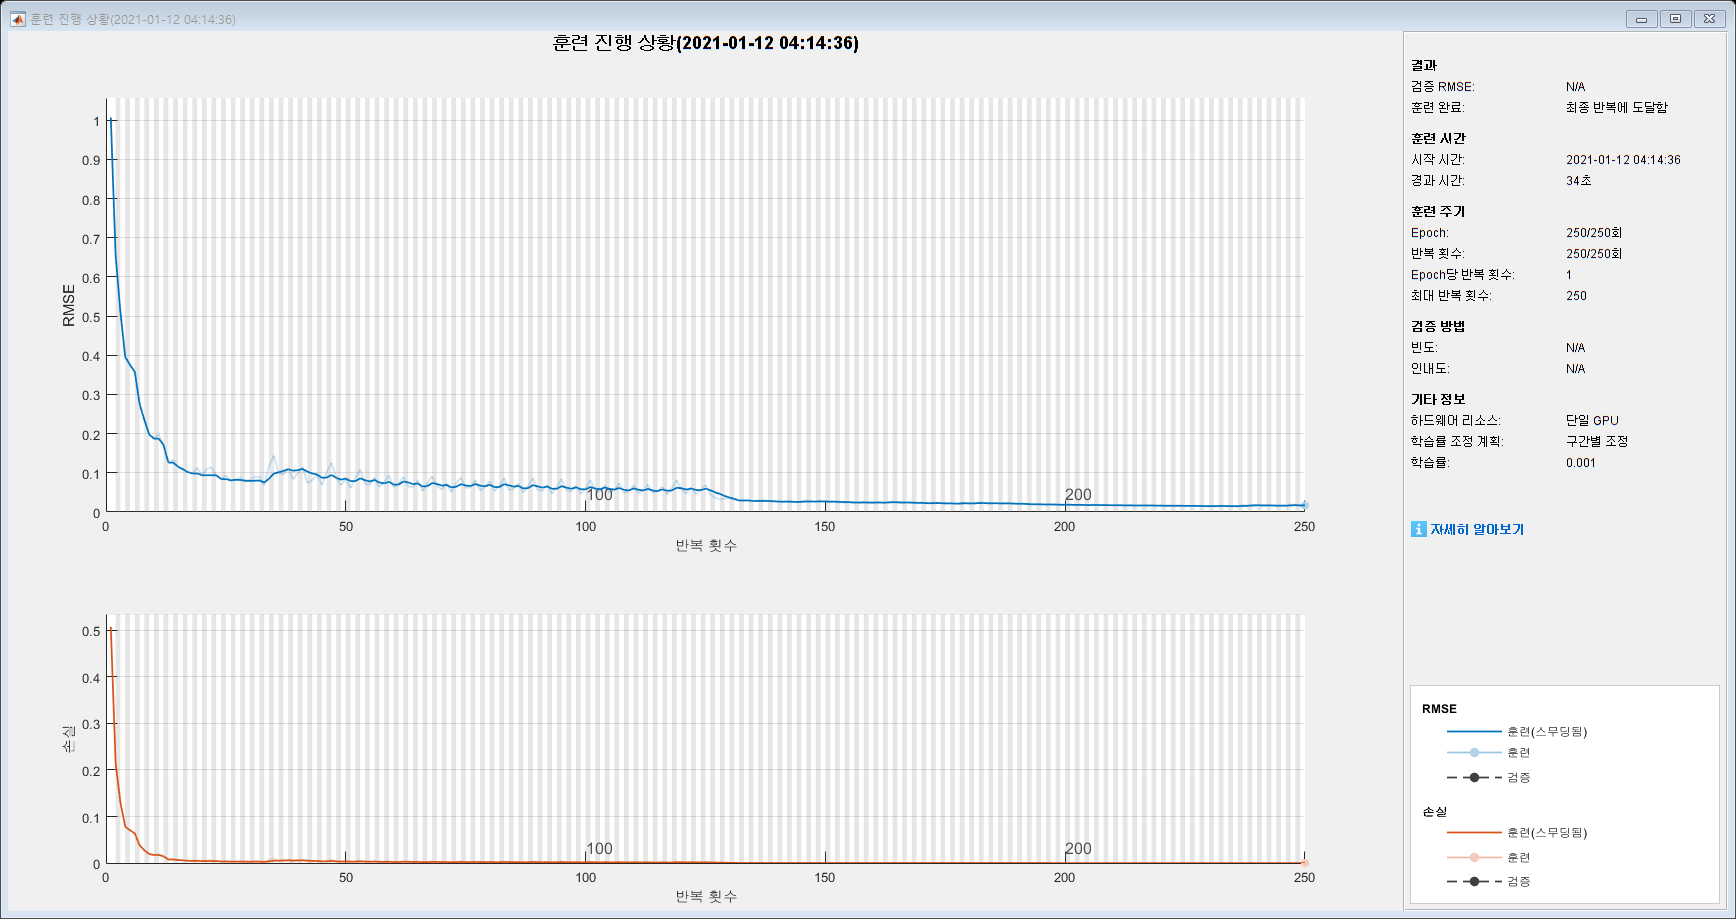

net = trainNetwork(XTrain,YTrain,layers,options);

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

%net = predictAndUpdateState(net,XTrain);
%[net,YPred] = predictAndUpdateState(net,YTrain(end));

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

rmse = 0.9370

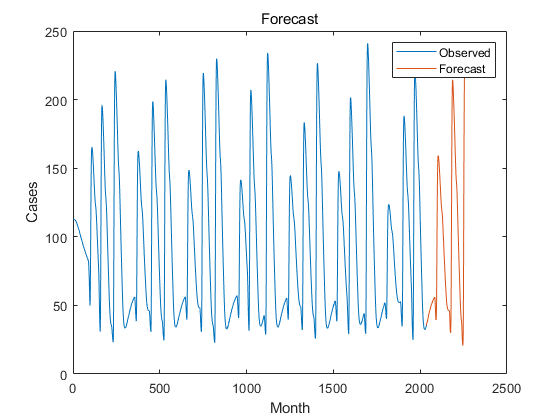


figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[d(numTimeStepsTrain) YPred],'-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

function run_Callback(hObject, eventdata, handles)
% hObject    handle to run (see GCBO)
% eventdata  reserved - to be defined in a future version of MATLAB
% handles    structure with handles and user data (see GUIDATA)
 display('T1DMS Simulation IN PROGRESS, please wait . . .')
warning('off','all')
load sim_data Lstruttura Lscenario hardware
Lst=Lstruttura;
hd=hardware;
Nscenario=length(Lscenario);

for scen=1:Nscenario
    scenario=Lscenario(scen);
    
    if isempty(scenario.CR)
        scenario.CR='off';
    end
    
    sc_checked=get(handles.scenario_check,'Value');
    sb_checked=get(handles.subject_check,'Value');
    
    if ~sc_checked
        error_window('string','You need to select a scenario')
    elseif ~sb_checked
        error_window('string','You need to select at least 1 subject')
    else
        
%          sb = statusbar(hObject,['Scenario ' num2str(scen) '/' num2str(Nscenario) ' simulation in progress, please wait.']);
%                 sb.getParent.setVisible(1)
%                 set(sb.ProgressBar, 'Visible','on', 'Indeterminate','off');
%                 set(sb.ProgressBar, 'Visible','on', 'StringPainted','on');
%                 set(sb.ProgressBar,'Value',0)
        n=length(Lstruttura);
        
        rep=round(str2double(get(handles.repeat,'String')))*get(handles.repInd,'Value');
        
        if isempty(rep)
            rep=1;
        elseif rep<=0
            rep=1;
        end
        
        %creating a single randomgenerator per patient ensures independence
        %accross subject AND reproducibility.
        seed=str2double(get(handles.seed,'String'));
        if isnan(seed) || isempty(seed)
            seed=sum(100*clock);
        end
        for ind=1:n
            Lst(ind).rg=RandStream.create('mrg32k3a','NumStreams',n,'StreamIndices',ind,'Seed',seed);
        end
        
        bck_SQinsulin=scenario.SQ_insulin.signals;
        
        bck_meals=scenario.meals;
        bck_meal_announce=scenario.meal_announce;
        scenario_bck=scenario;
        tic % tic toc tic toc tic toc tic toc 
        addpath('controller setup')
%      
%      
%      
%      
%       
%      
%      
%      
%      

        parfor ind=1:n    % % 
            try
            sc=scenario_bck;
            struttura=Lst(ind);
            display(['simulating ' struttura.names])
            drawnow
            res_aux=run_simulation(sc,struttura,hd,rep,bck_meals,...
                bck_meal_announce,bck_SQinsulin,ind);
            resultsb(ind).res=res_aux;
            display(['end of ' struttura.names])        
            catch e                
                rethrow(e);
            end
        end

        toc % tic toc tic toc tic toc tic toc 
        for ind=1:n
            for k=1:rep
                results((ind-1)*rep+k)=resultsb(ind).res{k};
            end
        end
        
        clear resultsb
        data(scen).results=results;
        data(scen).scenario=scenario_bck;
        data(scen).hardware=hd;    % % for Audit in dataFile
        % ***** Store ctrlsetup settings ***** 
        % Subject Specific (Quest calculated) values are reported as 0
        % All Values may not be used in The Controller
         data(scen).ctrlsetup = ctrlsetup(...
             struct('basal',0,'OB',0,'MD',0,'names',0,'weight',0,'fastingBG',0),...
             [],...
             [],...
             [],[]);  % {'basal','OB','MD','CR','CF','name','BW','fastingBG'});
            data(scen).ctrlsetup.Note_1 = 'Subject Specific Values (Quest.*, OB, CR, basal, etc.) may be reported = 0';
            data(scen).ctrlsetup.Note_2 = 'ctrlsetup.m ctrller.* Info is not necessarily included in Simulink controller';
            data(scen).ctrlsetup.Note_3 = 'ctrlsetup.m Info provided for auditing purposes';
        %***** Done storing ctrolsetup *****
        save sim_results data
        display('T1DMS Simulation of Subjects is complete, Computing Outcomes . . .')
        load sim_out output
        delete(['tempres' filesep '*'])
        %    
        create_output(results,output,[scenario.Tdose(2:end)' scenario.dose(2:end)'],scenario.Treg,get(handles.saveastxt,'Value'));
        clear results
           SCEN1 = int2str(scen);
           SCEN2 = int2str(Nscenario);
            message1 = strcat('Scenario_', SCEN1,'_of_',SCEN2);
            disp(message1)        
            display('T1DMS Simulation has ended . . .')
            if scen < Nscenario
                display('WAIT for next Scenario Simulation . . .')
                display('T1DMS Simulation IN PROGRESS, please wait . . .')
            end

    end
    
        
    guidata(hObject,handles)
    
    
end
if length(Lscenario)>1
    popstat=accrossscenario_output('String','Do you want summary statistics and graphs (accross scenario)?');
    if popstat
        load sim_out output
        accross_output(data,output,get(handles.saveastxt,'Value'));
        display(' accross_outpu')
    end
end
end